# **Άσκηση 1**

**Ονοματεπώνυμο: Εμμανουηλίδης Κωνσταντίνος**

**Α.Μ.: 57315**

Ο σκοπός της πρώτης άσκησης είναι η εξαγωγή των παραθύρων του δοθέντος αρχείου ήχου, η ανακατασκευή τους και η σύγκριση του ανακατευασκευασμένου αρχείου με το αρχικό ηχητικό αρχείο.

Αρχικά, εισάγουμε το αρχείο ήχου:

clear;
clc;
[x,Fs] = audioread("guit2.wav");

Έπειτα, το αναλύουμε σε παράθυρα:

X = frame_wind(x,256,0.5);

Κάνουμε επανασύνθεση των παραθύρων για να πάρουμε την αρχική κυματομορφή ήχου:

y = frame_recon(X,0.5);

Τέλος, μπορούμε να ακούσουμε το αρχικό ηχητικό αρχείο και μετά το επανασυντεθιμένο και να τα συγκρίνουμε:

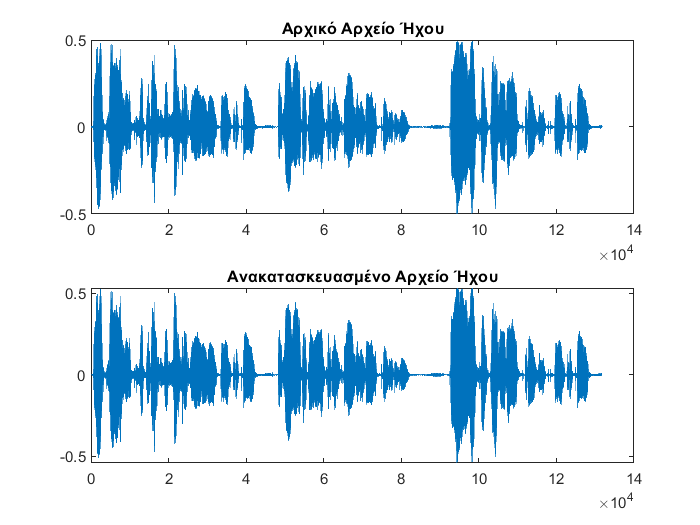

%Compare initial and reconstωructed audio
%Uncomment to hear reconstructed audio
%soundsc(x,16000);
%soundsc(y,16000);

% Create Plots
subplot(2,1,1)
plot(x);
title("Αρχικό Αρχείο Ήχου")
subplot(2,1,2)
plot(y);
title("Ανακατασκευασμένο Αρχείο Ήχου")

Ακούγοντας τα ηχητικά αποτελέσματα και συγκρίνοντας τις κυματομορφές τους παρατηρούμε ότι τα δύο ηχητικά αρχεία μοιάζουν πάρα πολύ.

Συνεπώς, συμπεραίνουμε ότι έχει γίνει τέλεια επανασύνθεση του αρχικού ήχου από τα παράθυρα στα οποία αναλύθηκε στην αρχή.